**Lecture HW3**

Steven Henderson

**Question 4**

A baseball has been batted and is moving in air. It is subject to drag that is quadratic in the velocity Fd = −cv2 ˆv = −cvv. Use the following parameters: c = 1 2 CD ρ d2, CD = 0.47, diameter d = 74 mm, mass = 145 g, initial speed = 45 m/s, initial angle = 30 degrees, ρair = 1.2 kg/m3, and initial position (x, z) = (0, 1) m.

1. Derive the differential equations for the position x(t) and z(t).


$$\begin{array}{l}
F_d =-\mathrm{cv}\vec{v} =m\frac{d\vec{v} }{\mathrm{dt}}\\
\frac{{\mathrm{dv}}_x }{\mathrm{dt}}=-\frac{c}{m}v_x \vec{v} =\frac{{\mathrm{dx}}^2 }{d^2 t}\\
\frac{{\mathrm{dv}}_z }{\mathrm{dt}}=-g-\frac{c}{m}v_z \vec{v} =\frac{{\mathrm{dz}}^2 }{d^2 t}\\
\vec{v} =\sqrt{v_x^2 +v_z^2 }
\end{array}$$


2. Write a MATLAB livescript to find the speeds and positions vx(t), vz (t), x(t), z(t). Use enough time to ensure the object hits the ground. Give plots of each of the four quantities (as a function of time), and add aplot showing z as a function of x. You might be tempted to use your code from your earlier solution, but see the note at the end.

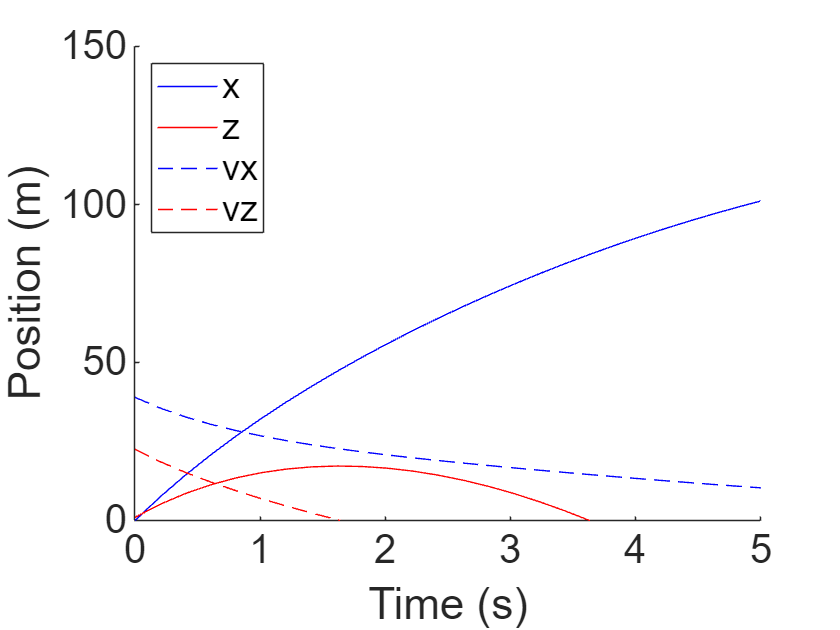

% Second coupled ODE function with drag
function out = drag(t, pos)
    % Define initial variables
    CD = 0.47 ; % Coefficient of drag 
    rho = 1.2 ; % Density of air (kg/m^3)
    d = 74 / 1000 ; % Diameter (m)
    m = 145 / 1000 ; % Mass of object (kg)
    c = (1/2)*CD*rho*d^2 ; % Drag constant
    g = 10 ; % Gravity (m/s^2)

    % Extract varibles from input
    x = pos(1) ; %(m)
    vx = pos(2) ; %(m/s)
    z = pos(3) ; %(m)
    vz = pos(4) ; %(m/s)

    % Setup equations
    f1 = -(c/m)*vx*sqrt(vx^2 + vz^2) ;
    f2 = -g - (c/m)*vz*sqrt(vx^2 + vz^2) ;

    % Return column vector of 4 differentials to be solved be ode45 (velocity x, acceleration x, velocity z, acceleration z)
    out = [vx; f1; vz; f2] ;
end
% Initial variable setuo
iv = 45 ; % Initial Velocity (m/s)
iphi = 30 ; % Initial angle (degrees)
ipos = [0; iv*cosd(iphi); 1; iv*sind(iphi)] ; 
tspan = linspace(0, 20, 100) ; % (s)

% Call ode45 to solve function defined above (drag)
[t, pos] = ode45(@drag, tspan, ipos) ;

% Extract solutions
x_sol = pos(:, 1) ; %(m)
vx_sol = pos(:, 2) ; %(m/s)
z_sol = pos(:, 3) ; %(m)
vz_sol = pos(:, 4) ; %(m/s)

% Plot velocities and positions in the x and z axis
clf
hold on
plot(tspan, x_sol, 'b')
plot(tspan, z_sol, 'r') 
plot(tspan, vx_sol, 'b--')
plot(tspan, vz_sol, 'r--')
hold off
ylabel('Position (m)')
xlabel('Time (s)')
ylim([0, 150])
xlim([0, 5])
legend('x', 'z', 'vx', 'vz', 'Location', 'northwest')
set(gca, 'fontsize', 20) ;

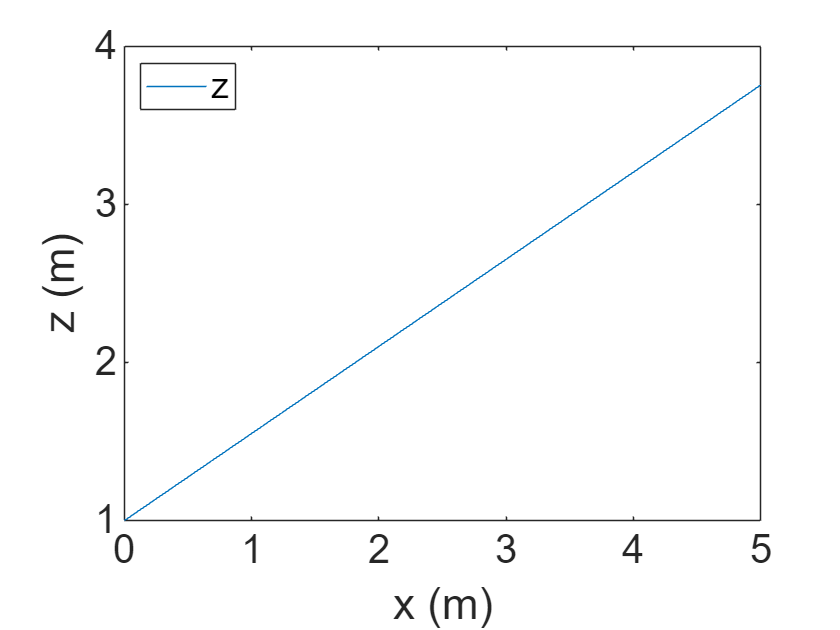

% Plot z as a function of x
clf
plot(x_sol, z_sol)
ylabel('z (m)')
xlabel('x (m)')
%ylim([0, 150])
xlim([0, 5])
legend('z', 'Location', 'northwest')
set(gca, 'fontsize', 20) ;

3. Demonstrate that your code is correct (or that the results make sense) by comparing your derived position (x(t) and z(t)) to the position in the case of no drag. That is, overlay the positions and velocities with no drag in all the plots you generated earlier. Give two sentences explaining why you conclude that your results make sense.

*Solutions without drag*


$$\begin{array}{l}
\frac{{\mathrm{dx}}^2 }{d^2 t}=0\\
\frac{{\mathrm{dz}}^2 }{d^2 t}=-g
\end{array}$$


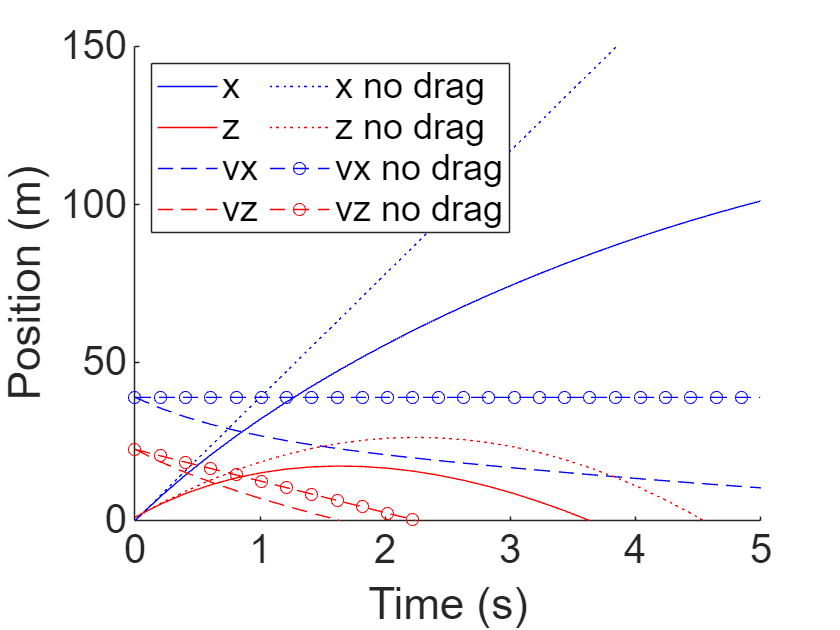

% Second ODE function for no drag solution
function out = nodrag(t, pos)
    % Initial variables
    g = 10 ; % Gravity (m/s^2)

    % Extract varibles from input
    x = pos(1) ; %(m)
    vx = pos(2) ; %(m/s)
    z = pos(3) ; %(m)
    vz = pos(4) ; %(m/s)

    % Setup ODE
    f1 = 0 ;
    f2 = -g ;

    % Return column vector with (velocity x, acceleration x, velocity y, acceleration y)
    out = [vx; f1; vz; f2] ;
end

% Call ode45 on function set above (nodrag)
[t, pos_nodrag] = ode45(@nodrag, tspan, ipos) ;

% Extract solutions
x_sol_nodrag = pos_nodrag(:, 1) ; %(m)
vx_sol_nodrag = pos_nodrag(:, 2) ; %(m/s)
z_sol_nodrag = pos_nodrag(:, 3) ; %(m)
vz_sol_nodrag = pos_nodrag(:, 4) ; %(m/s)

% Plot no drag solution velocity and positions against drag solution
% velocity and positions
clf
hold on 
plot(tspan, x_sol, 'b')
plot(tspan, z_sol, 'r') 
plot(tspan, vx_sol, 'b--')
plot(tspan, vz_sol, 'r--')
plot(tspan, x_sol_nodrag, 'b:')
plot(tspan, z_sol_nodrag, 'r:') 
plot(tspan, vx_sol_nodrag, 'b--o')
plot(tspan, vz_sol_nodrag, 'r--o')
hold off
ylabel('Position (m)')
xlabel('Time (s)')
ylim([0, 150])
xlim([0, 5])
legend('x', 'z', 'vx', 'vz', 'x no drag', 'z no drag', 'vx no drag', 'vz no drag', 'Location', 'northwest', 'NumColumns', 2)
set(gca, 'fontsize', 20) 

This looks good as each of the positions and velocities for the solution with no drag follow the same paths as the positions and velocities of the solution with drag. Each of the positions and velocities for the no drag solution are slightly larger than the solutions with drag which makes sense as without drag the object would fly further and move faster. Another note is to notice the x velocity of the no drag solution is constant which makes sense as there would be no forces acting upon it in the x direction.

4. Find the initial angle at which the ball needs to be batted to achieve maximum range, and compare it to the angle for the case of no drag. Since the batter can only aim crudely, find this angle to within ∼ ±2.5 deg (a span of about 5 degrees), and give the range. Be sure to explain how you found the span in angle and the range. Compare to the range and the angle for maximum range without drag. Give approximate values and explain how you obtained them. The phrase ‘maximum range’ refers to the distance on the ground from (x, z) = (0, 1) m to (xrange, z = 0) m.

The process I used was to loop through angles from 0 to 90 and find their solutions and where the z value is less than 0. Then I added all the ranges using the index returned by one function to find the max range which is then returned along with the angle that is associated with this range. Find_range function returns the range index of a paticular solutions while, find_angle returns the angle of maximum range. It was found that,

max range = 86.2236 m

max angle = 40$\pm$5 degrees

% Function to find range of drag solution with initial angle iphi
function [range_index, x_sol, vx_sol, z_sol, vz_sol] = find_range(iphi, iv, ix, iz, tspan)
    % Setup initial values
    ipos = [ix; iv*cosd(iphi); iz; iv*sind(iphi)] ;

    % Call ode45 for solution
    [t, pos] = ode45(@drag, tspan, ipos) ;

    % Extract solutions
    x_sol = pos(:, 1) ; %(m)
    vx_sol = pos(:, 2) ; %(m/s)
    z_sol = pos(:, 3) ; %(m)
    vz_sol = pos(:, 4) ; %(m/s)

    % Find when z < 0 and return index
    for i = 1:length(z_sol)
        % Check wether z < 0
        if z_sol(i) < 0
            % Return index when z < 0
            range_index = i ;
            break;
        end
    end 
end

% Function to find max range of object when starting from a span of angles
function [angle, range, x_vals, vx_vals, z_vals, vz_vals] = find_angle(span_angles, iv, ix, iz, tspan)
    % Initial variable allocation
    ranges = zeros(1, length(span_angles)) ; %(m)
    x_vals = zeros(length(tspan)) ; %(m)
    vx_vals = zeros(length(tspan)) ; %(m/s)
    z_vals = zeros(length(tspan)) ; %(m)
    vz_vals = zeros(length(tspan)) ; %(m/s)

    % Loop through angles plugging into find_range and add their solutions and range to variables
    % declared above
    for i = 1:length(span_angles)
        [range_index, x_sol, vx_sol, z_sol, vz_sol] = find_range(span_angles(i), iv, ix, iz, tspan) ;
        x_vals(:, i) = x_sol ;
        vx_vals(:, i) = vx_sol ;
        z_vals(:, i) = z_sol ;
        vz_vals(:, i) = vz_sol; 
        ranges(i) = x_sol(range_index, :) ;
    end

    % Return max range and its index
    [range, idx] = max(ranges) ;
    % Return max angle
    angle = span_angles(idx) ;
end

% Setup initial variables
span_angles = 0:5:90 ; % 0 -> 90 degrees with resolution of 5 degrees
iv = 45 ; %(m/s)
ix = 0 ; %(m)
iz = 0 ; %(m)
% Call find_angle to get max angle and range as well as values for
% velocities and position to plot
[angle, range, x_vals, vx_vals, z_vals, vz_vals] = find_angle(span_angles, iv, ix, iz, tspan) ;
disp(['Max range angle: ', num2str(angle), '+-5 degrees', ' Max range: ', num2str(range), ' (m)']) ;

Max range angle: 40+- 5 degrees Max range: 86.2236 (m)


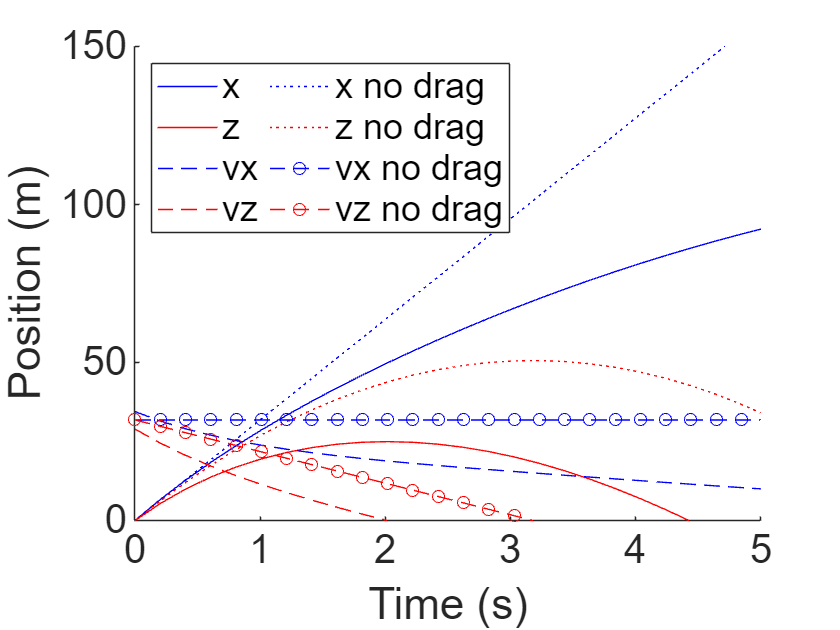

% Use angle of max range to find a solution using drag function from before
[t, max_range] = ode45(@drag, tspan, [ix, iv*cosd(angle), iz, iv*sind(angle)]) ;
% It is known that 45 degrees is the farthest range when there is no drag,
% plug 45 degrees into ode45 to find solution with no drag
[t, max_range_nodrag] = ode45(@nodrag, tspan, [ix, iv*cosd(45), iz, iv*sind(45)]) ;

% Extract solutions
x_sol_max_range = max_range(:, 1) ; %(m)
vx_sol_max_range = max_range(:, 2) ; %(m/s)
z_sol_max_range = max_range(:, 3) ; %(m)
vz_sol_max_range = max_range(:, 4) ; %(m/s)
x_sol_max_range_nodrag = max_range_nodrag(:, 1) ; %(m)
vx_sol_max_range_nodrag = max_range_nodrag(:, 2) ; %(m/s)
z_sol_max_range_nodrag = max_range_nodrag(:, 3) ; %(m)
vz_sol_max_range_nodrag = max_range_nodrag(:, 4) ; %(m/s)

% Plot max range drag solution against max range no drag solution
clf
hold on 
plot(tspan, x_sol_max_range, 'b')
plot(tspan, z_sol_max_range, 'r') 
plot(tspan, vx_sol_max_range, 'b--')
plot(tspan, vz_sol_max_range, 'r--')
plot(tspan, x_sol_max_range_nodrag, 'b:')
plot(tspan, z_sol_max_range_nodrag, 'r:') 
plot(tspan, vx_sol_max_range_nodrag, 'b--o')
plot(tspan, vz_sol_max_range_nodrag, 'r--o')
hold off
ylabel('Position (m)')
xlabel('Time (s)')
ylim([0, 150])
xlim([0, 5])
legend('x', 'z', 'vx', 'vz', 'x no drag', 'z no drag', 'vx no drag', 'vz no drag', 'Location', 'northwest', 'NumColumns', 2)
set(gca, 'fontsize', 20) 